clear all
clc

% General parameters and conversion gains

%   conversion gains
rpm2rads = 2*pi/60;                 %   [rpm]   -> [rad/s]
rads2rpm = 60/2/pi;                 %   [rad/s] -> [rpm]

rpm2degs = 360/60;                  %   [rpm]   -> [deg/s]
degs2rpm = 60/360;                  %   [deg/s] -> [rpm]

deg2rad = pi/180;                   %   [deg]   -> [rad]
rad2deg = 180/pi;                   %   [rad]   -> [deg]

ozin2Nm = 0.706e-2;                 %   [oz*inch] -> [N*m]

% DC motor nominal parameters
%   brushed DC-motor Faulhaber 2338S006S
mot.R    = 2.6;                     %   armature resistance
mot.L    = 180e-6;                  %   armature inductance
mot.Kt   = 1.088 * ozin2Nm;         %   torque constant
mot.Ke   = 0.804e-3 * rads2rpm;     %   back-EMF constant
mot.J    = 5.523e-5 * ozin2Nm;      %   rotor inertia
mot.B    = 0.0;                     %   viscous friction coeff (n.a.)      
mot.eta  = 0.69;                    %   motor efficiency
mot.PN   = 3.23/mot.eta;            %   nominal output power
mot.UN   = 6;                       %   nominal voltage
mot.IN   = mot.PN/mot.UN;           %   nominal current
mot.tauN = mot.Kt*mot.IN;           %   nominal torque
mot.taus = 2.42 * ozin2Nm;          %   stall torque
mot.w0   = 7200 * rpm2rads;         %   no-load speed

% Gearbox nominal parameters
%   planetary gearbox Micromotor SA 23/1 
gbox.N1   = 14;                     %   1st reduction ratio (planetary gearbox)
gbox.eta1 = 0.80;                   %   gearbox efficiency 

%   external transmission gears
gbox.N2   = 1;                      %   2nd reduction ratio (external trasmission gears)
gbox.J72  = 1.4e-6;                 %   inertia of a single external 72 tooth gear      
gbox.eta2 = 1;                      %   external trasmission efficiency (n.a.)

%   overall gearbox data
gbox.N   = gbox.N1*gbox.N2;         %   total reduction ratio
gbox.eta = gbox.eta1*gbox.eta2;     %   total efficiency
gbox.J   = 3*gbox.J72;              %   total inertia (at gearbox output)

% Mechanical load nominal parameters

% hub params
mld.Jh = 6.84e-4; % moment of inertia
mld.Bh = 2.5e-4; % viscous friction coeff
mld.tausf =1.0e-2; % static friction (estimated)


% beam & elastic joint params
mld.Jb = 1.4e-3; % moment of inertia
mld.d = 5.0e-2; % flex joint damping coeff (estimated)
mld.wn = 24.5; % flex joint natural freq (estimated)
mld.Bb = mld.Jb * 2*mld.d*mld.wn; % beam viscous friction
mld.k = mld.Jb * mld.wn^2; % flex joint stiffness

% Voltage driver nominal parameters
%   op-amp circuit params
drv.R1 = 7.5e3;                     %   op-amp input resistor (dac to non-inverting in)
drv.R2 = 1.6e3;                     %   op-amp input resistor (non-inverting in to gnd)
drv.R3 = 1.2e3;                     %   op-amp feedback resistor (output to  inverting in)
drv.R4 = 0.5e3;                     %   op-amp feedback resistor (inverting in to gnd)
drv.C1 = 100e-9;                    %   op-amp input capacitor
drv.outmax = 12;                    %   op-amp max output voltage

%   voltage driver dc-gain      
drv.dcgain = drv.R2/(drv.R1+drv.R2) * (1 + drv.R3/drv.R4);

%   voltage driver time constant
drv.Tc = drv.C1 * drv.R1*drv.R2/(drv.R1+drv.R2);

% Sensors data
%   shunt resistor
sens.curr.Rs = 0.5;   

%   Hewlett-Packard HEDS-5540#A06 optical encoder
sens.enc.ppr = 500*4;                               %   pulses per rotation
sens.enc.pulse2deg = 360/sens.enc.ppr;              %   [pulses] -> [deg]
sens.enc.pulse2rad = 2*pi/sens.enc.ppr;             %   [pulses] -> [rad]
sens.enc.deg2pulse = sens.enc.ppr/360;              %   [deg] -> [pulses]
sens.enc.rad2pulse = sens.enc.ppr/2/pi;             %   [rad] -> [pulses]

%   potentiometer 1 (Spectrol 138-0-0-103) - installed on motor box
sens.pot1.range.R      = 10e3;                                          %   ohmic value range 
sens.pot1.range.V      = 5;                                             %   voltage range
sens.pot1.range.th_deg = 345;                                           %   angle range [deg]
sens.pot1.range.th     = sens.pot1.range.th_deg * deg2rad;              %   angle range [rad]                 
sens.pot1.deg2V        = sens.pot1.range.V / sens.pot1.range.th_deg;    %   sensitivity [V/deg]
sens.pot1.rad2V        = sens.pot1.range.V / sens.pot1.range.th;        %   sensitivity [V/rad]
sens.pot1.V2deg        = 1/sens.pot1.deg2V;                             %   conversion gain [V] -> [deg]
sens.pot1.V2rad        = 1/sens.pot1.rad2V;    %   conversion gain [V] -> [rad]

% potentiometer 2 (Spectrol 357−0−0−103) − installed on hub
sens.pot2.range.R = 10e3; % ohmic value range
sens.pot2.range.V = 5; % voltage range
sens.pot2.range.th_deg = 340; % angle range [deg]
sens.pot2.range.th = sens.pot2.range.th_deg * deg2rad; % angle range [rad]
sens.pot2.deg2V = sens.pot2.range.V / sens.pot2.range.th_deg; % sensitivity [V/deg]
sens.pot2.rad2V = sens.pot2.range.V / sens.pot2.range.th; % sensitivity [V/rad]
sens.pot2.V2deg = 1/sens.pot2.deg2V; % conversion gain [V] −> [deg]
sens.pot2.V2rad = 1/sens.pot2.rad2V; % conversion gain [V] −> [rad]
sens.pot2.noise.var = 3.5e-7; % out noise variance [V^2]

% Data acquisition board (daq) data
%   NI PCI-6221 DAC data
daq.dac.bits = 16;                                  %   resolution (bits)
daq.dac.fs   = 10;                                  %   full scale 
daq.dac.q    = 2*daq.dac.fs/(2^daq.dac.bits-1);     %	quantization

%   NI PCI-6221 ADC data
daq.adc.bits = 16;                                  %   resolution (bits)
daq.adc.fs   = 10;                                  %   full scale (as set in SLDRT Analog Input block)
daq.adc.q    = 2*daq.adc.fs/(2^daq.adc.bits-1);     %   quantization 

% Sampling time
Ts = 1e-3;

% motore parameter Lab3
lab3.Jeq = mot.J + mld.Jh/gbox.N^2;
lab3.Tausf = 4.748915e-03;
% lab3.Tausf = 0;
% lab3.Tausf = 0;
lab3.Beq = 8.540115e-07;
Req = mot.R + sens.curr.Rs;

% PID required parameters

ts_5 = 0.85;          
Mp = 0.3;      
delta_d = log(1/Mp)/sqrt(pi^2 + log(1/Mp)^2);
wg = 3/(delta_d*ts_5);


% Derivative 1
fSS = 50;
wcSS = 2*pi*fSS;
deltaSS = 1/(sqrt(2));

% Derivative 2
fd = 20;
wcd = 2*pi*fd;
deltad = 1/(sqrt(2));

% Motor parameter obtained in lab0
% real.Jeq = 5.875341e-07;
% real.Beq = 8.540115e-07;
% real.Tausf = 4.748915e-03;
% tausf_value = real.Tausf;


% pid coefficients

% kp = 11.4589;
% kd = 0.5164;
% ki = 12.7141;
% tl = 0.01;

kp = 1.139446e+01;
kd = 8.071364e-01;
ki = 4.021428e+01; 
tl = 1.013929e-02;


beam.d = 5.0e-2;
beam.wn = 24.5;
beam.Jb = 1.4e-3;
beam.Bb = beam.Jb*2*beam.d*beam.wn;
joint.k = beam.Jb*beam.wn^2;



## Define state space function

A = [0                 0                                                                  1                                                   0;
     0                 0                                                                  0                                                   1;
     0           joint.k/((gbox.N^2)*lab3.Jeq)                                -1/lab3.Jeq*(lab3.Beq+(mot.Kt*mot.Ke/Req))                           0;
     0     -joint.k/beam.Jb-joint.k/(lab3.Jeq*(gbox.N^2))             -beam.Bb/beam.Jb + 1/lab3.Jeq*(lab3.Beq+(mot.Kt*mot.Ke/Req))           -beam.Bb/beam.Jb ];

B = [0;      0;      (mot.Kt*drv.dcgain)/(gbox.N*lab3.Jeq*Req);     -(mot.Kt*drv.dcgain)/(gbox.N*lab3.Jeq*Req)];
C = [1   0   0   0];
D = 0;

## Nominal  tracking

nominal_phi = atan(sqrt(1-delta_d^2)/delta_d);
% nominal_poles1 = [exp(1i*(-pi + nominal_phi/2))].*wg;
nominal_poles1 = -8.1265 - 5.5885i;
nominal_poles3 = -3.5294 - 9.2095i;
% nominal_poles3 = [exp(1i*(-pi+nominal_phi))].*wg;
nominal_poles = [nominal_poles1 conj(nominal_poles1) nominal_poles3 conj(nominal_poles3)];
nominal_K = real(place(A, B, nominal_poles));
nominal_N = [A B; C D]\[zeros(4,1); 1];
nominal_Nx = nominal_N(1:4);
nominal_Nu = nominal_N(5);


## Robust tracking


robust_phi = atan(sqrt(1-delta_d^2)/delta_d);
robust_N = [A B; C D]\[zeros(4,1); 1];
robust_Nx = robust_N(1:4);
robust_Nu = robust_N(5);
robust_Ae = [0 C; zeros(4,1) A];
robust_Be = [0; B];
robust_Ce = [0 C];

robust_poles1 = [exp(1i*(-pi - robust_phi))].*wg;
robust_poles3 = [exp(1i*(-pi - robust_phi/2))].*wg;
robust_poles5 = -wg;


robust_poles = [robust_poles1 conj(robust_poles1) robust_poles3 conj(robust_poles3) robust_poles5];

robust_ke = place(robust_Ae, robust_Be, robust_poles);
robust_ki = robust_ke(1);
robust_k = robust_ke(2:5);

## Position state-space control LQR methods point 1

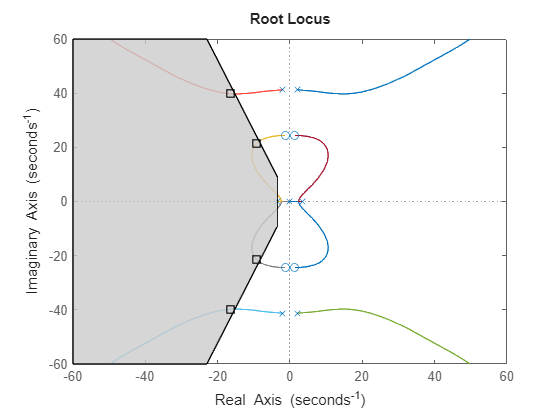

% Define sysG e sysGp state space models
sysG = ss(A,B,C,0);
sysGp = ss(-A,-B,C,0);

% Define verticale line limit on root locus to fulfill ts_5 request
sigma_max = -3 / ts_5;

% Le linee oblique sono definite da phi cge è l'angolo tra la linee obliqua
% e l'asse x negativo

% Define allowed space polygon

x = [sigma_max   sigma_max                        -60/tan(nominal_phi)  -60 -60 -60 -60/tan(nominal_phi) sigma_max];
y = [     0       -sigma_max*tan(nominal_phi)                  60          60   0  -60          -60 sigma_max*tan(nominal_phi)];

% plot root locus graph
figure;
hold on;


% Create allowed space area
patch(x, y, [0.8 0.8 0.8], 'FaceAlpha', 0.8);


rlocus(sysG * sysGp);
r_lqr = 0.00026;
k_lqr = lqr(sysG, C'*C, r_lqr);
closed_poles = eig(A - B*k_lqr);
plot(real(closed_poles), imag(closed_poles), 'ks', 'MarkerSize', 7, 'LineWidth', 1.2);
axis([-60 60 -60 60]);
hold off;

#### Position state-space control LQR methods point 3 (Bryson's rule)

% Matrix Q definition

% limit values
tetha_h_bar = 0.3*50*deg2rad;
tetha_d_bar = pi/36;
u_bar = 10;

% Q diagonal coefficients
q11_Bryson = 1/(tetha_h_bar)^2;
q22_Bryson = 1/(tetha_d_bar)^2;
q33_Bryson = 0;
q44_Bryson = 0;
Q_Bryson = diag([q11_Bryson, q22_Bryson,q33_Bryson,q44_Bryson]);

% Define r as in the handout part 6.2)
R_Bryson = 1/(u_bar)^2; 

sysP_Bryson = ss(A,B,C,D);

k_Bryson = lqr(sysP_Bryson,Q_Bryson,R_Bryson);


#### Position state-space control LQR methods point 5)  lqr robust (+integral action)

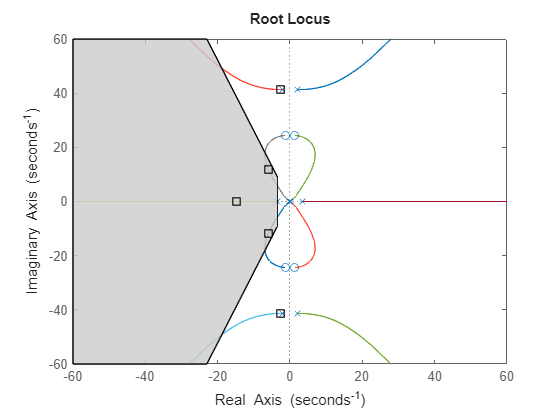

lqr_robust_Ae = [0 C; zeros(4,1) A];
lqr_robust_Be = [0; B];
lqr_robust_Ce = [1 0 0 0 0];

% Seem the system is not controllable
lqr_robust_sysGe = ss(lqr_robust_Ae, lqr_robust_Be, lqr_robust_Ce, D);
lqr_robust_sysGpe = ss(-lqr_robust_Ae, -lqr_robust_Be, lqr_robust_Ce, D);


x = [sigma_max   sigma_max                        -60/tan(nominal_phi)  -60 -60 -60 -60/tan(nominal_phi) sigma_max];
y = [     0       -sigma_max*tan(nominal_phi)                  60          60   0  -60          -60 sigma_max*tan(nominal_phi)];

% plot root locus graph
figure;
hold on;


% Create allowed space area
patch(x, y, [0.8 0.8 0.8], 'FaceAlpha', 0.8);


rlocus(lqr_robust_sysGe * lqr_robust_sysGpe);
lqr_robust_r = 0.000013; % consider only the low frequency eigenvalue
ke_lqr_robust = lqr(lqr_robust_sysGe, lqr_robust_Ce'*lqr_robust_Ce, lqr_robust_r);

closed_poles_robust = eig(lqr_robust_Ae - lqr_robust_Be*ke_lqr_robust);
plot(real(closed_poles_robust), imag(closed_poles_robust), 'ks', 'MarkerSize', 7, 'LineWidth', 1.2);
axis([-60 60 -60 60]);
hold off;

lqr_robust_Ki = ke_lqr_robust(1);
lqr_robust_K = ke_lqr_robust(2:5);